clear all;

load("pontos.mat");

[yupper,ylower] = envelope(pontos_5graus)

yupper =     8.2088    6.7850    6.7575    6.4039    6.3817    6.2227    6.2057    6.1275    6.1061    6.0664    6.0531    6.0455    6.0313    6.0392    6.0359    6.0577    6.0572    6.0938    6.0898    6.1375    6.1474    6.1955    6.2057    6.2674    6.2812    6.3449    6.3481    6.4201    6.4185    6.4805    6.4840    6.5304    6.5051    6.5355    6.4971    6.5067    6.4494    6.4286    6.3559    6.3243    6.2493    6.2056    6.1172    6.0775    5.9935    5.9481    5.8742    5.8297    5.7709    5.7217


ylower =    -2.0474   -0.6236   -0.5961   -0.2424   -0.2203   -0.0613   -0.0443    0.0339    0.0554    0.0950    0.1083    0.1159    0.1301    0.1222    0.1256    0.1037    0.1042    0.0677    0.0716    0.0239    0.0141   -0.0341   -0.0443   -0.1059   -0.1198   -0.1834   -0.1867   -0.2587   -0.2571   -0.3190   -0.3226   -0.3690   -0.3437   -0.3741   -0.3356   -0.3453   -0.2880   -0.2672   -0.1945   -0.1628   -0.0879   -0.0442    0.0442    0.0839    0.1679    0.2133    0.2872    0.3317    0.3905    0.4397


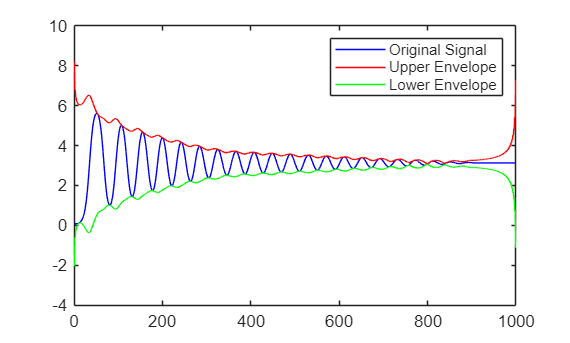

plot(pontos_5graus, 'b', 'DisplayName', 'Original Signal');
hold on;
plot(yupper, 'r', 'DisplayName', 'Upper Envelope');
plot(ylower, 'g', 'DisplayName', 'Lower Envelope');
legend show;
hold off;

P1 = pontos_5graus(692);
P2 = pontos_5graus(732);
Td = 0.08;

delta = log(P1/P2);
lambda = delta / Td;


save("lambda.mat", "lambda")